## **Transonic Aerodynamics - HW1**

Shalom Carmona

Nicolas Tran

Wave equation

clear; clc; close all;

% setup
c = 0.5; % wave speed
L = pi; % domain [0, pi]
N = 201; % grid points
dx = L/(N-1);
x  = linspace(0, L, N);

% ic: square pulse
u0 = zeros(size(x));
u0(x >= 0.5 & x <= 1.0) = 1.0;

x_mid0   = 0.75;
t_target = (2.5 - x_mid0)/c;
fprintf('dx = %.5f, t_target = %.5f (c = %.3f)\n', dx, t_target, c);

dx = 0.01571, t_target = 3.50000 (c = 0.500)


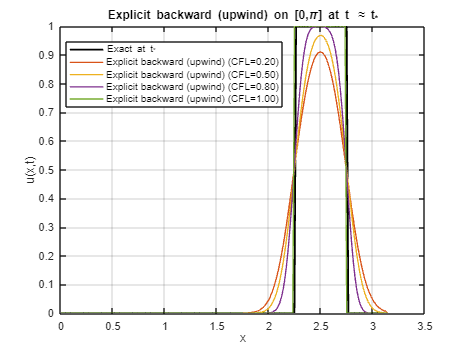

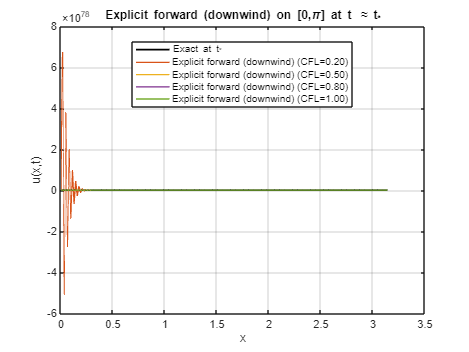

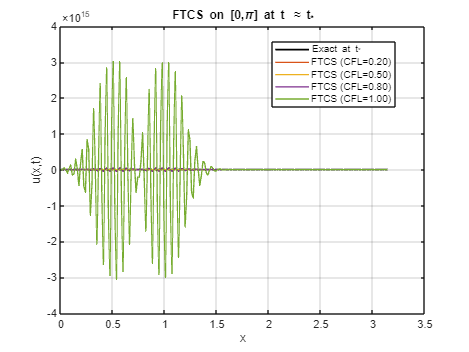

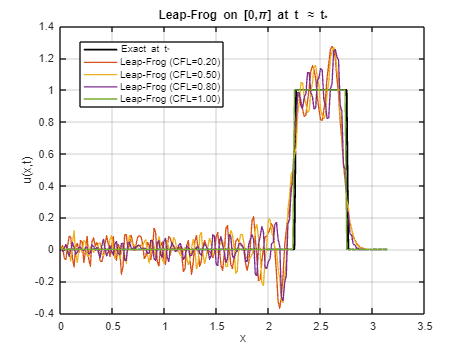

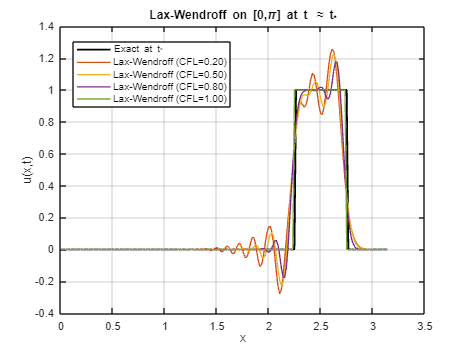

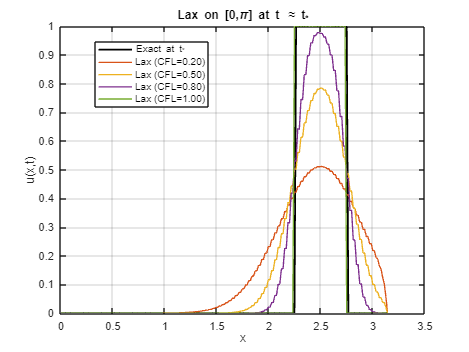


% cfl values
CFL_list = [0.2 0.5 0.8 1.0];

% exact sol
u_exact_t = exact_solution_square(x, t_target, c);

% schemes
scheme_names = {'Explicit backward (upwind)', 'Explicit forward (downwind)', ...
                'FTCS', 'Leap-Frog', 'Lax-Wendroff', 'Lax'};

scheme_funcs = {@upwind_scheme, @forward_explicit_scheme, ...
                @ftcs_scheme, @leapfrog_scheme, @lax_wendroff_scheme, @lax_scheme};

% each scheme for cfls
for s = 1:numel(scheme_names)
    figure; hold on; box on; grid on;
    plot(x, u_exact_t, 'k-', 'LineWidth', 1.6);
    legends = {'Exact at t_*'};

    for q = 1:numel(CFL_list)
        CFL = CFL_list(q);
        dt = CFL * dx / c;
        n_steps = max(1, round(t_target/dt));
        t_final = n_steps * dt;  %closest to tgt
        u_num = scheme_funcs{s}(u0, x, dx, dt, c, t_final);
        plot(x, u_num, 'LineWidth', 1.2);
        legends{end+1} = sprintf('%s (CFL=%.2f)', scheme_names{s}, CFL);
    end

    xlabel('x'); ylabel('u(x,t)');
    title(sprintf('%s on [0,\\pi] at t \\approx t_*', scheme_names{s}));
    legend(legends, 'Location','best');
end

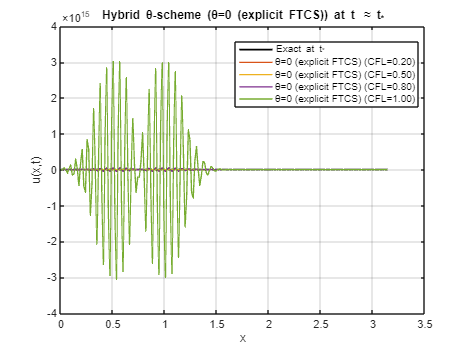

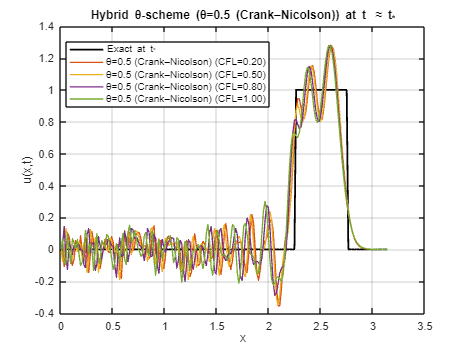

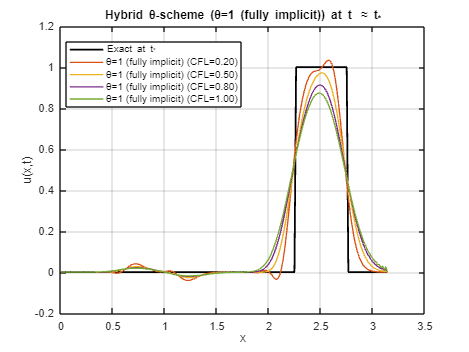


thetas = [0.0, 0.5, 1.0];
names_theta = {'θ=0 (explicit FTCS)','θ=0.5 (Crank–Nicolson)','θ=1 (fully implicit)'};

for r = 1:numel(thetas)
    figure; hold on; box on; grid on;
    plot(x, u_exact_t, 'k-', 'LineWidth', 1.6);
    legends = {'Exact at t_*'};

    for q = 1:numel(CFL_list)
        CFL = CFL_list(q);
        dt = CFL * dx / c;
        n_steps = max(1, round(t_target/dt));
        t_final = n_steps * dt;
        u_theta = theta_scheme(u0, x, dx, dt, c, t_final, thetas(r));
        plot(x, u_theta, 'LineWidth', 1.2);
        legends{end+1} = sprintf('%s (CFL=%.2f)', names_theta{r}, CFL);
    end

    xlabel('x'); ylabel('u(x,t)');
    title(sprintf('Hybrid θ-scheme (%s) at t \\approx t_*', names_theta{r}));
    legend(legends, 'Location','best');
end

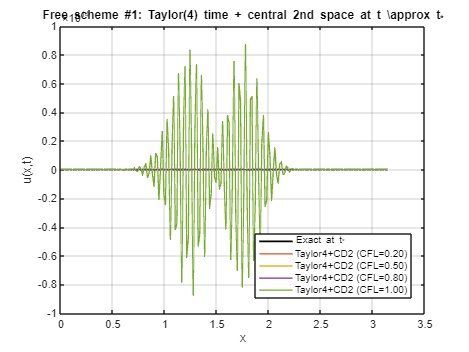


%free scheme option #1: taylor(4) time + central 2nd space
% u^{n+1} = u^n - c dt u_x + (c^2 dt^2/2) u_xx - (c^3 dt^3/6) u_xxx + (c^4 dt^4/24) u_xxxx
figure; hold on; box on; grid on;
plot(x, u_exact_t, 'k-', 'LineWidth', 1.6);
legends = {'Exact at t_*'};

for q = 1:numel(CFL_list)
    CFL = CFL_list(q);
    dt = CFL * dx / c;
    n_steps = max(1, round(t_target/dt));
    t_final = n_steps * dt;
    u_t4 = taylor4_central2_scheme(u0, x, dx, dt, c, t_final);
    plot(x, u_t4, 'LineWidth', 1.2);
    legends{end+1} = sprintf('Taylor4+CD2 (CFL=%.2f)', CFL);
end

xlabel('x'); ylabel('u(x,t)');
title('Free scheme #1: Taylor(4) time + central 2nd space at t \\approx t_*');
legend(legends, 'Location','best');

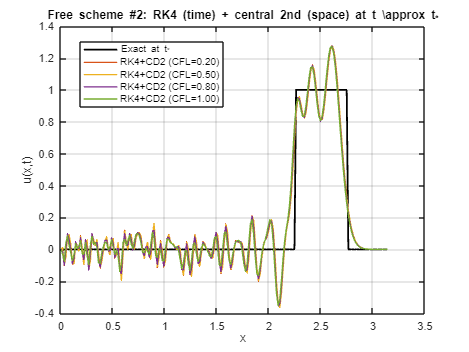


%free scheme option #2: rk4 time + central 2nd space
figure; hold on; box on; grid on;
plot(x, u_exact_t, 'k-', 'LineWidth', 1.6);
legends = {'Exact at t_*'};

for q = 1:numel(CFL_list)
    CFL = CFL_list(q);
    dt = CFL * dx / c;
    n_steps = max(1, round(t_target/dt));
    t_final = n_steps * dt;
    u_rk4 = rk4_central2(u0, x, dx, dt, c, t_final);
    plot(x, u_rk4, 'LineWidth', 1.2);
    legends{end+1} = sprintf('RK4+CD2 (CFL=%.2f)', CFL);
end

xlabel('x'); ylabel('u(x,t)');
title('Free scheme #2: RK4 (time) + central 2nd (space) at t \\approx t_*');
legend(legends, 'Location','best');


%functions

function u_exact = exact_solution_square(x, t, c)
    s = c*t;
    xi = x - s;
    u_exact = zeros(size(x));
    u_exact(xi >= 0.5 & xi <= 1.0) = 1.0;
end

function u_new = apply_exact_dirichlet_square(u, x, t, c)
    u(1)   = exact_solution_square(x(1),   t, c);
    u(end) = exact_solution_square(x(end), t, c);
    u_new = u;
end

%schemes
function u_out = upwind_scheme(u0, x, dx, dt, c, t_final)
    N = numel(u0); u = u0(:)'; CFL = c*dt/dx; n_steps = max(1, round(t_final/dt));
    for n = 1:n_steps
        u_new = u;
        for i = 2:N
            u_new(i) = u(i) - CFL*(u(i) - u(i-1));
        end
        u = apply_exact_dirichlet_square(u_new, x, n*dt, c);
    end
    u_out = u;
end

function u_out = forward_explicit_scheme(u0, x, dx, dt, c, t_final)
    N = numel(u0); u = u0(:)'; CFL = c*dt/dx; n_steps = max(1, round(t_final/dt));
    for n = 1:n_steps
        u_new = u;
        for i = 1:N-1
            u_new(i) = u(i) - CFL*(u(i+1) - u(i));
        end
        u = apply_exact_dirichlet_square(u_new, x, n*dt, c);
    end
    u_out = u;
end

function u_out = ftcs_scheme(u0, x, dx, dt, c, t_final)
    N = numel(u0); u = u0(:)'; CFL = c*dt/dx; n_steps = max(1, round(t_final/dt));
    for n = 1:n_steps
        u_new = u;
        for i = 2:N-1
            u_new(i) = u(i) - 0.5*CFL*(u(i+1) - u(i-1));
        end
        u = apply_exact_dirichlet_square(u_new, x, n*dt, c);
    end
    u_out = u;
end

function u_out = lax_wendroff_scheme(u0, x, dx, dt, c, t_final)
    N = numel(u0); u = u0(:)'; CFL = c*dt/dx; n_steps = max(1, round(t_final/dt));
    for n = 1:n_steps
        u_new = u;
        for i = 2:N-1
            u_new(i) = u(i) ...
                - 0.5*CFL*(u(i+1)-u(i-1)) ...
                + 0.5*CFL^2*(u(i+1) - 2*u(i) + u(i-1));
        end
        u = apply_exact_dirichlet_square(u_new, x, n*dt, c);
    end
    u_out = u;
end

function u_out = lax_scheme(u0, x, dx, dt, c, t_final)
    N = numel(u0); u = u0(:)'; CFL = c*dt/dx; n_steps = max(1, round(t_final/dt));
    for n = 1:n_steps
        u_new = u;
        for i = 2:N-1
            u_new(i) = 0.5*(u(i+1)+u(i-1)) - 0.5*CFL*(u(i+1)-u(i-1));
        end
        u = apply_exact_dirichlet_square(u_new, x, n*dt, c);
    end
    u_out = u;
end

function u_out = leapfrog_scheme(u0, x, dx, dt, c, t_final)
    N = numel(u0);
    u_prev = u0(:)';                                 % u^{n-1}
    u = upwind_single_step_square(u0(:)', x, dx, dt, c, 1*dt); % u^{n}
    CFL = c*dt/dx; n_steps = max(1, round(t_final/dt));
    if n_steps == 1, u_out = u; return; end
    for n = 2:n_steps
        u_new = u;
        for i = 2:N-1
            u_new(i) = u_prev(i) - CFL*(u(i+1) - u(i-1));
        end
        u_new = apply_exact_dirichlet_square(u_new, x, n*dt, c);
        u_prev = u; u = u_new;
    end
    u_out = u;
end

function u1 = upwind_single_step_square(u0, x, dx, dt, c, t_now)
    N = numel(u0); CFL = c*dt/dx; u_new = u0;
    for i = 2:N
        u_new(i) = u0(i) - CFL*(u0(i) - u0(i-1));
    end
    u1 = apply_exact_dirichlet_square(u_new, x, t_now, c);
end

% θ-scheme - implicit
function u_out = theta_scheme(u0, x, dx, dt, c, t_final, theta)
    N = numel(u0); u = u0(:)'; CFL = c*dt/dx; n_steps = max(1, round(t_final/dt));
    a  = -theta*CFL/2;  b = 1;  c1 = theta*CFL/2;
    lower = a  * ones(N,1); main = b*ones(N,1); upper = c1*ones(N,1);
    for n = 1:n_steps
        RHS = u;
        for j = 2:N-1
            RHS(j) = u(j) - (1-theta)*(CFL/2)*(u(j+1) - u(j-1));
        end
        t = n*dt;
        RHS(1) = exact_solution_square(x(1),   t, c);
        RHS(N) = exact_solution_square(x(end), t, c);
        A = spdiags([lower main upper], [-1 0 1], N, N);
        A(1,:) = 0; A(1,1) = 1; A(N,:) = 0; A(N,N) = 1;
        u = (A \ RHS(:)).';
    end
    u_out = u;
end

%free scheme #1: taylor4 time + central 2nd space
function u_out = taylor4_central2_scheme(u0, x, dx, dt, c, t_final)
    u = u0(:)'; n_steps = max(1, round(t_final/dt));
    for n = 1:n_steps
        t = (n-1)*dt;
       
        uL_ghost = exact_solution_square(x(1) - dx, t, c);
        uR_ghost = exact_solution_square(x(end) + dx, t, c);
        uext = [uL_ghost, u, uR_ghost];

        Nloc = numel(u);
        ux    = zeros(1,Nloc);
        uxx   = zeros(1,Nloc);
        uxxx  = zeros(1,Nloc);
        uxxxx = zeros(1,Nloc);

        for i = 2:Nloc-1
            ie = i+1;
            % 1st (3-pt)
            ux(i)    = (uext(ie+1) - uext(ie-1)) / (2*dx);
            % 2nd (3-pt)
            uxx(i)   = (uext(ie+1) - 2*uext(ie) + uext(ie-1)) / (dx^2);
            % 3rd (5-pt, 2nd-order)
            uxxx(i)  = (uext(ie-2) - 2*uext(ie-1) + 2*uext(ie+1) - uext(ie+2)) / (2*dx^3);
            % 4th (5-pt, 2nd-order)
            uxxxx(i) = (uext(ie-2) - 4*uext(ie-1) + 6*uext(ie) - 4*uext(ie+1) + uext(ie+2)) / (dx^4);
        end

        u_new = u;
        for i = 2:Nloc-1
            u_new(i) = u(i) ...
                - c*dt*ux(i) ...
                + (c^2*dt^2/2)*uxx(i) ...
                - (c^3*dt^3/6)*uxxx(i) ...
                + (c^4*dt^4/24)*uxxxx(i);
        end

        tnp1 = n*dt;
        u_new(1)   = exact_solution_square(x(1),   tnp1, c);
        u_new(end) = exact_solution_square(x(end), tnp1, c);

        u = u_new;
    end
    u_out = u;
end

%free scheme #2: RK4 time + central 2nd space
function u_out = rk4_central2(u0, x, dx, dt, c, t_final)
    u = u0(:)'; n_steps = max(1, round(t_final/dt));
    for n = 0:n_steps-1
        t = n*dt;
        k1 = rhs_operator_square(u, x, dx, c, t);
        u1 = apply_exact_dirichlet_square(u + 0.5*dt*k1, x, t + 0.5*dt, c);
        k2 = rhs_operator_square(u1, x, dx, c, t + 0.5*dt);
        u2 = apply_exact_dirichlet_square(u + 0.5*dt*k2, x, t + 0.5*dt, c);
        k3 = rhs_operator_square(u2, x, dx, c, t + 0.5*dt);
        u3 = apply_exact_dirichlet_square(u + dt*k3, x, t + dt, c);
        k4 = rhs_operator_square(u3, x, dx, c, t + dt);
        u = u + (dt/6)*(k1 + 2*k2 + 2*k3 + k4);
        u = apply_exact_dirichlet_square(u, x, t + dt, c);
    end
    u_out = u;
end

function Lu = rhs_operator_square(u, x, dx, c, t)
    u = apply_exact_dirichlet_square(u, x, t, c);
    N = numel(u);
    dudx = zeros(1,N);
    for i = 2:N-1
        dudx(i) = (u(i+1) - u(i-1))/(2*dx);
    end
    dudx(1) = (u(2) - u(1))/dx; 
    dudx(N) = (u(N) - u(N-1))/dx;
    Lu = -c*dudx;
end
